# Pooling Testing to Reduce Prevalance rate of Covid-19 in Hong Kong

By the data provided by by the Center for Systems Science and Engineering (CSSE) at Johns Hopkins University, the number of new case perked at July 28, 2020, with 132 case 7-day average. Since Covid-19 test will only be positve after 1-2 week of exposure, we can take 112 on Auguest 4,2020 and caculate the prevalance rate (p) of 1708/7507000, which is 0.0227521% in Hong Kong. However the simulation in MATLAB is not that great. Therefore, I will only introduce one sick to the whole samples ranging from size of 50 to 200.

We are seeing great sucess of batch testing in China, each batch are five to 10 samples are tested. Only when the pool is position will an individual test will be carried, This is very ineffective since a second sample may need to be taken again or the whole group need to go under quarantine before the indivdual test result come out. Therefore there is matrix pooling  which provide accurate result but not very effective. Therefore in this project, we will investigate in pool testing method and other way to prevent spread of Covid-19.

## *Friendly reminder: all codes in livescript are the same as .m files. There are some minor adjustments, but they all work the same 

# Random pooling with Metropolis-Hastings algorithm

clear all
alpha=0;
n=24;
m=16;
k=2;
p=0.5;
max_iteration=100;
phi=eye(m,n);
for i=1:n
    temp=randperm(m);
    phi(temp(1:2),i)=1;
end
i=1;
iteration_no=1;
phi_new=phi;
while iteration_no<max_iteration
    while i<=n
        while true
            for j=1:m
                if rand<=p && phi_new(j,i)==1
                    temp=randi([1,m]);
                    while phi_new(temp,i)==1
                        temp=randi([1,m]);
                    end
                    [phi_new(temp,i) phi_new(j,i)]=deal(phi_new(j,i),phi_new(temp,i));
                end
            end
            flag=true;
            for kk=1:i-1
                flag=flag&&~isequal(phi_new(:,kk),phi_new(:,i));
            end
            if flag
                i=i+1;
                break
            end
        end
    end
    max_str=[];
    for ii=1:n-1
        for jj=1:ii-1
            max_str=[max_str phi_new(:,ii)'*phi_new(:,jj)];
        end
    end
    alpha_new=k-max(max_str);
    if alpha_new/alpha>rand
        alpha=alpha_new;
        phi=phi_new;
    end
    iteration_no=iteration_no+1;
end

Since we have no idea on which sample have Covid-19, we will need to test for the pool to see which pool got positive result for Covid-19 and also assigning random sample to this experiment.

[sample,y]=assigning_random(p,n,m,phi)

sample =      1     3     5     7     8     9    11    15    16    18    21    24


y = 16×1 logical array
   1
   0
   1
   0
   1
   1
   1
   1
   1
   0


# Two-pass adaptive testing for exact recovery

T=1:n;
T_round1=[];
T_round2=[];
i=1;
while i<=m
    if y(i)==0
        for j=find(phi(i,:)==1)
            T=T(T~=j);
        end
    else
        if numel(find(phi(i,:)==1))==1
            T_round1=[T_round1 i];
        end
    end
    i=i+1;
end
for i=T_round1
    T=T(T~=i);
end
for i=T
    if find(sample==i)
        T_round2=[T_round2 i];
    end
end
output=[T_round1 T_round2]

output =      1     3     5     7     8     9    11    15    16    18    21    24


# Single-pass non-adaptive testing for approximate recovery of test results

T=1:n;
T_round1=[];
w=find(y==1)';
i=1;
while i<=m
    if y(i)==0
        for j=find(phi(i,:)==1)
            T=T(T~=j);
        end
    else
        if numel(find(phi(i,:)==1))==1
            T_round1=[T_round1 i];
            w=w(w~=i);
        end
    end
    i=i+1;
end
for i=T_round1
    T=T(T~=i);
end
while ~isempty(w)
    j=[];
    for i=1:n
        temp_w=w;
        for k=find(phi(:,i)==1)'
            temp_w=temp_w(temp_w~=k);
        end
        j=[j numel(temp_w)];
    end
    j=find(j==min(j),1,'first');
    T_round1=[T_round1 j];
    T=T(T~=j);
    for i=find(phi(:,j)==1)'
        w=w(w~=i);
    end
end

sample

sample =      1     3     5     7     8     9    11    15    16    18    21    24


sort(output)

ans =      1     3     5     7     8     9    11    15    16    18    21    24


sort(T_round1)

ans =      1     2     5    11    16


# Pool Testing in Covid Detection

Since each simulation is unique and some may not spread due to low sample size or low social interaction as in real life. To reduce the complexity of this simulator. There are a few assumption: previously infected individual will stay immune to the virus and the vaccinated population will be immune to the virus too.

Also, when sick stay-at-home got pool-tested positive result, they will start moving to simulate that they are heading to quaratine camp but all positive result sample will become a star sign and they will not spread the virus to anyone.

From the simulation below, we can see that with a sample size of 200 and no other setting, the SIR model is very similar to the one in The Washington Post, it is a very good recreation of the simulation. Also, we can see that it will have the most maximum cocurrently sick compared with some vaccination ratio and people staying at home.

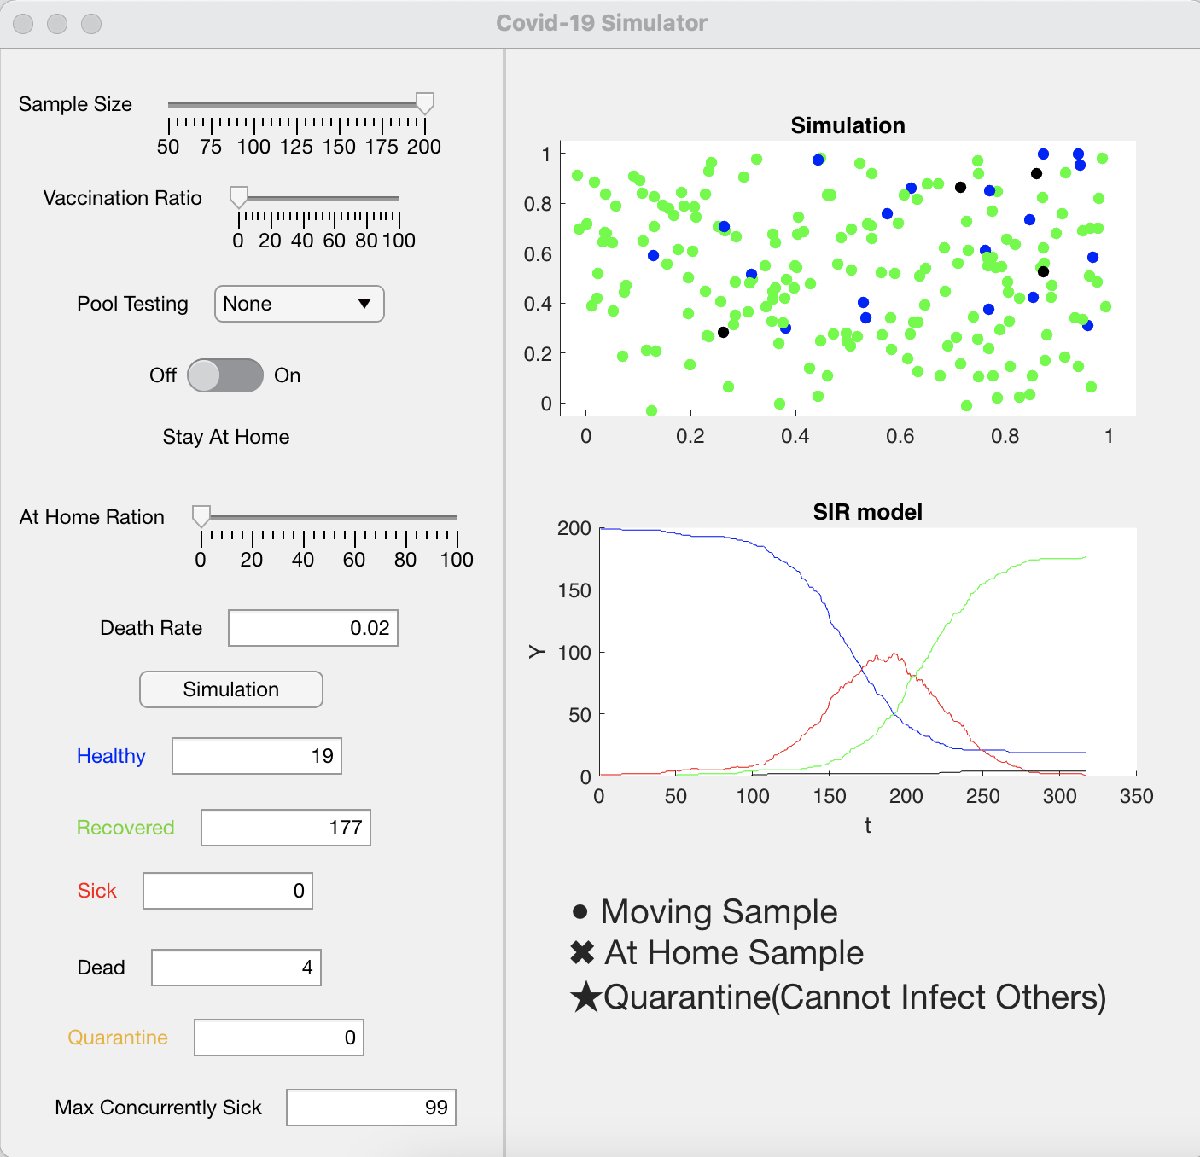

This is another model in The Washington Post with 75% of people social distancing and the rest are moving (cross symbol means social distancing and remain stationary while the other points can move freely everywhere). This have a significant difference compared to the previous simulation.

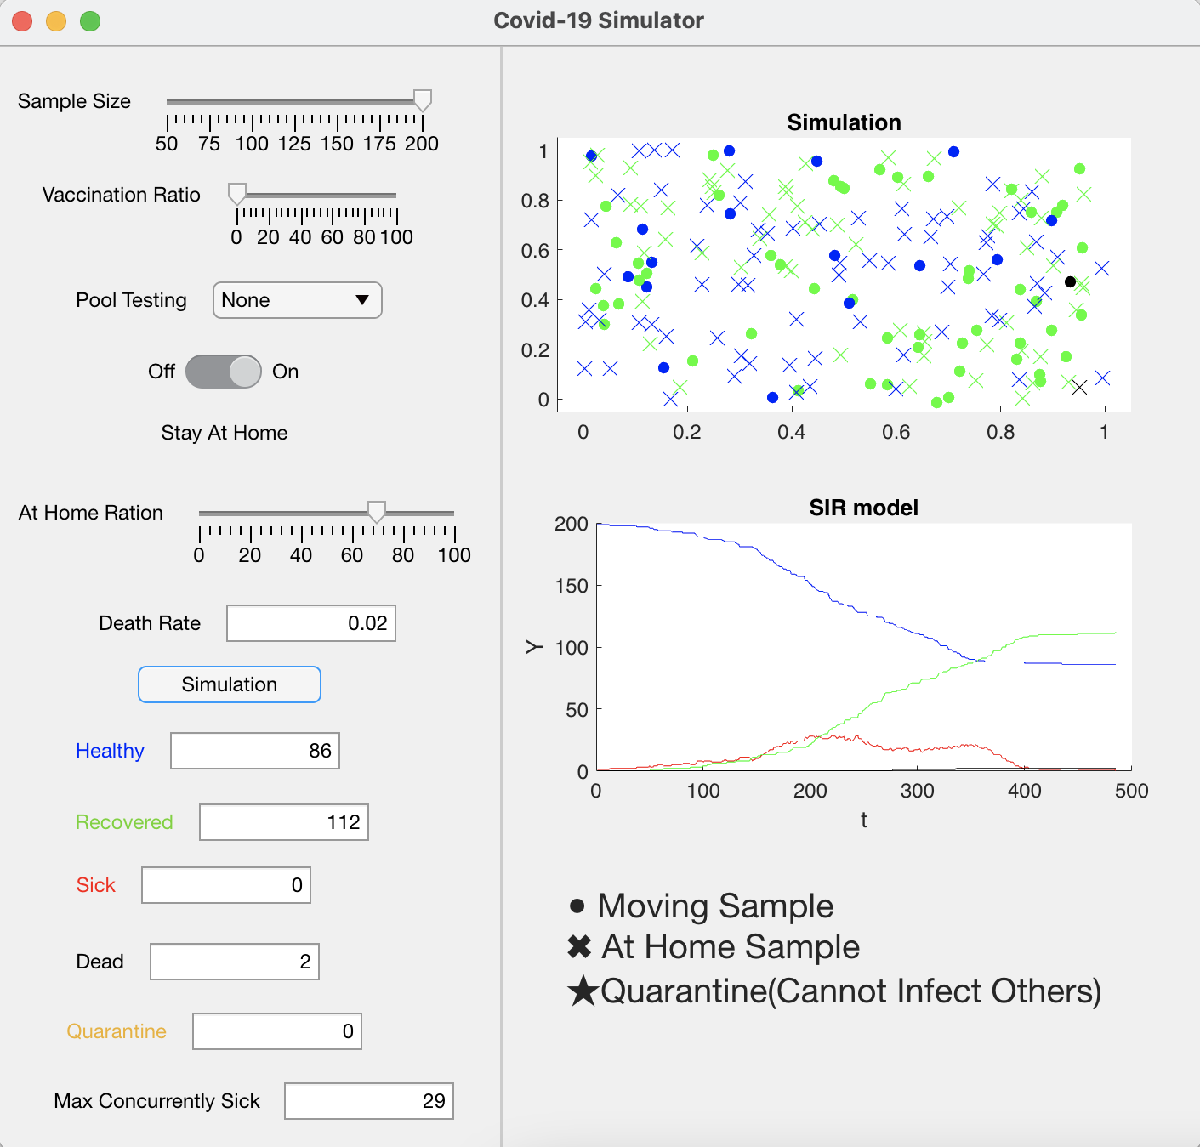

Even though there is one false-positive result, it got most of the sick people into quarantine and reduce the max cocurrently sick to a minimum.

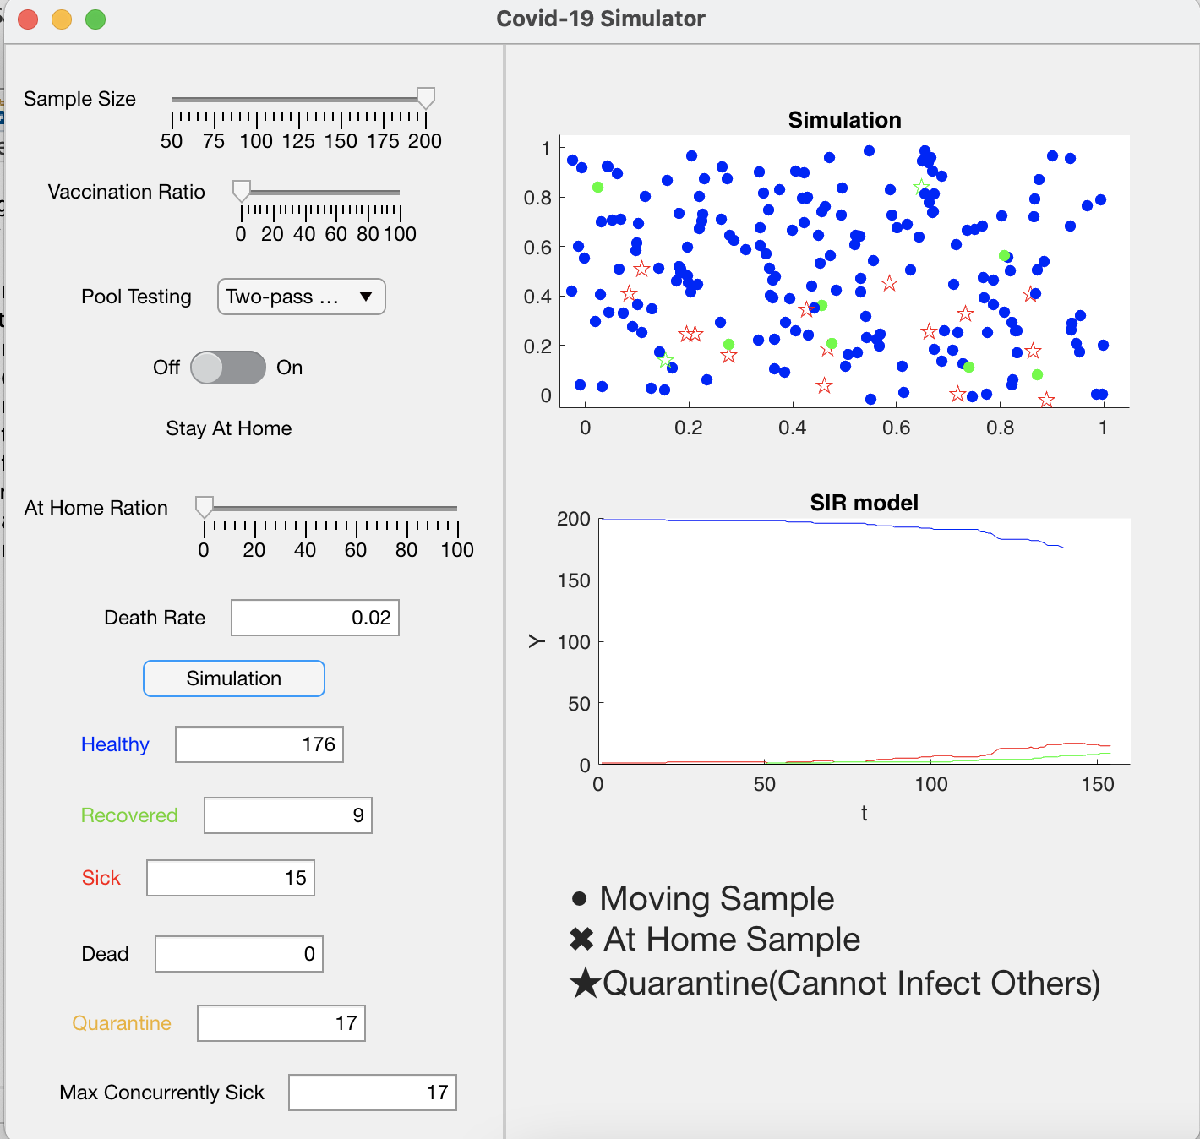

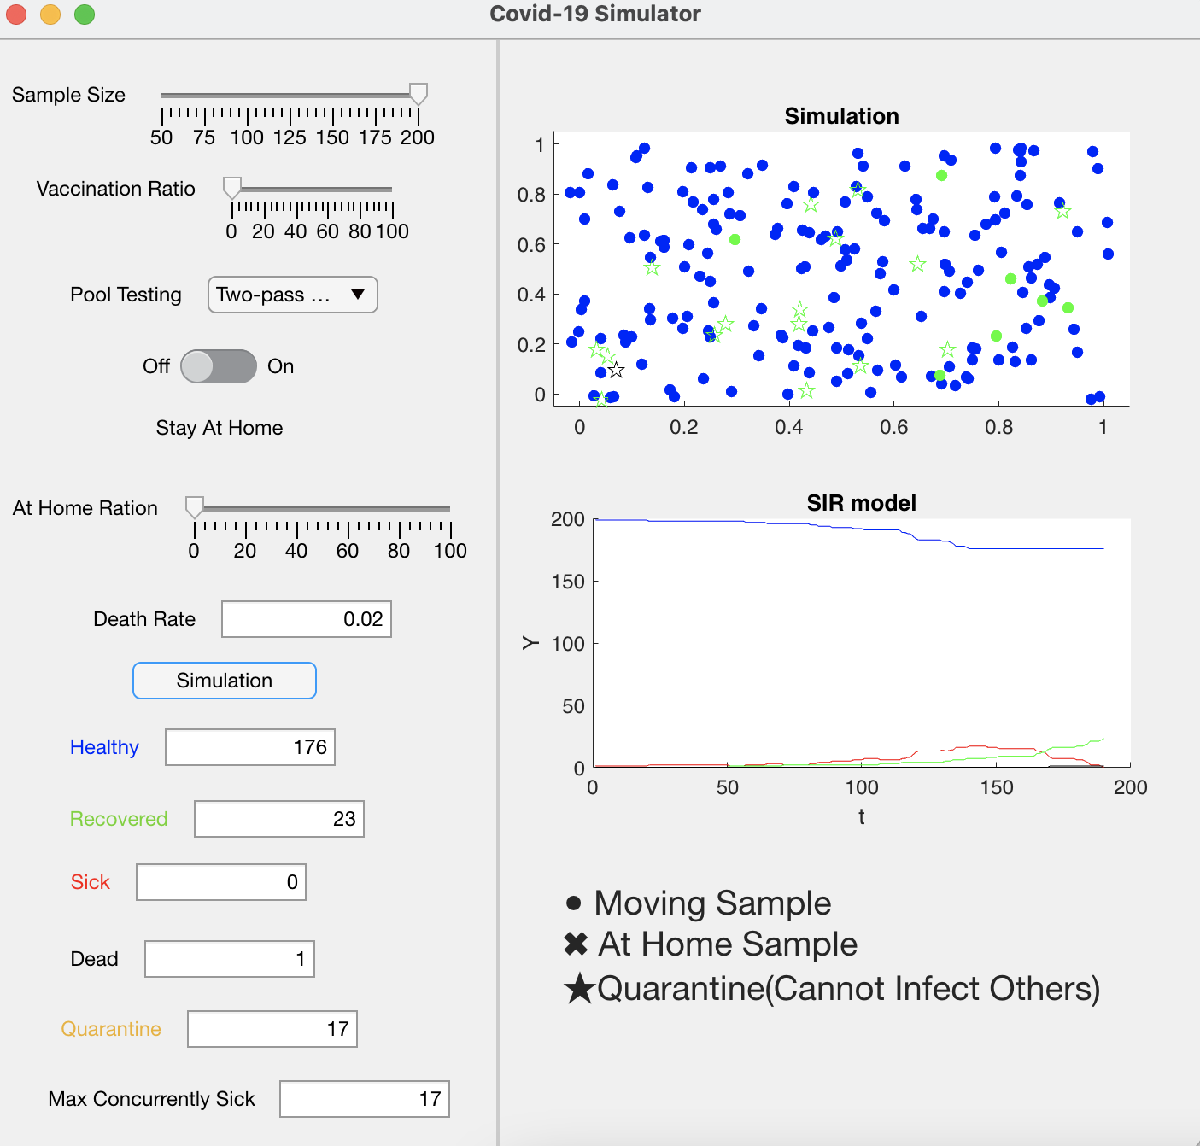

For single-pass pool testing, it has a low sensitivity and specificity, which is coherence with the article that provided this algorithm. 

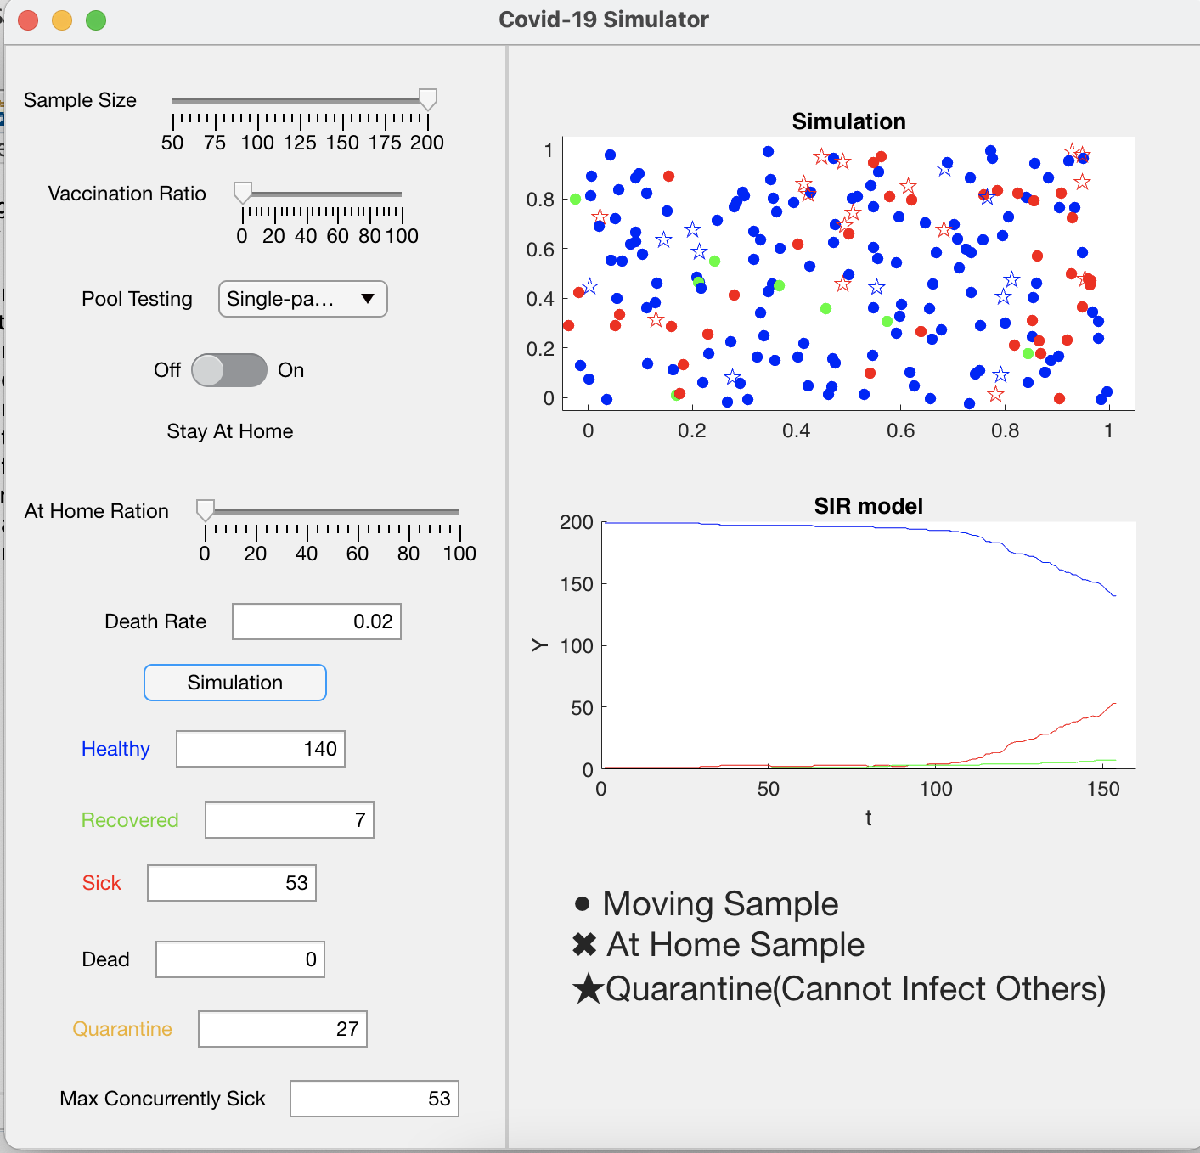

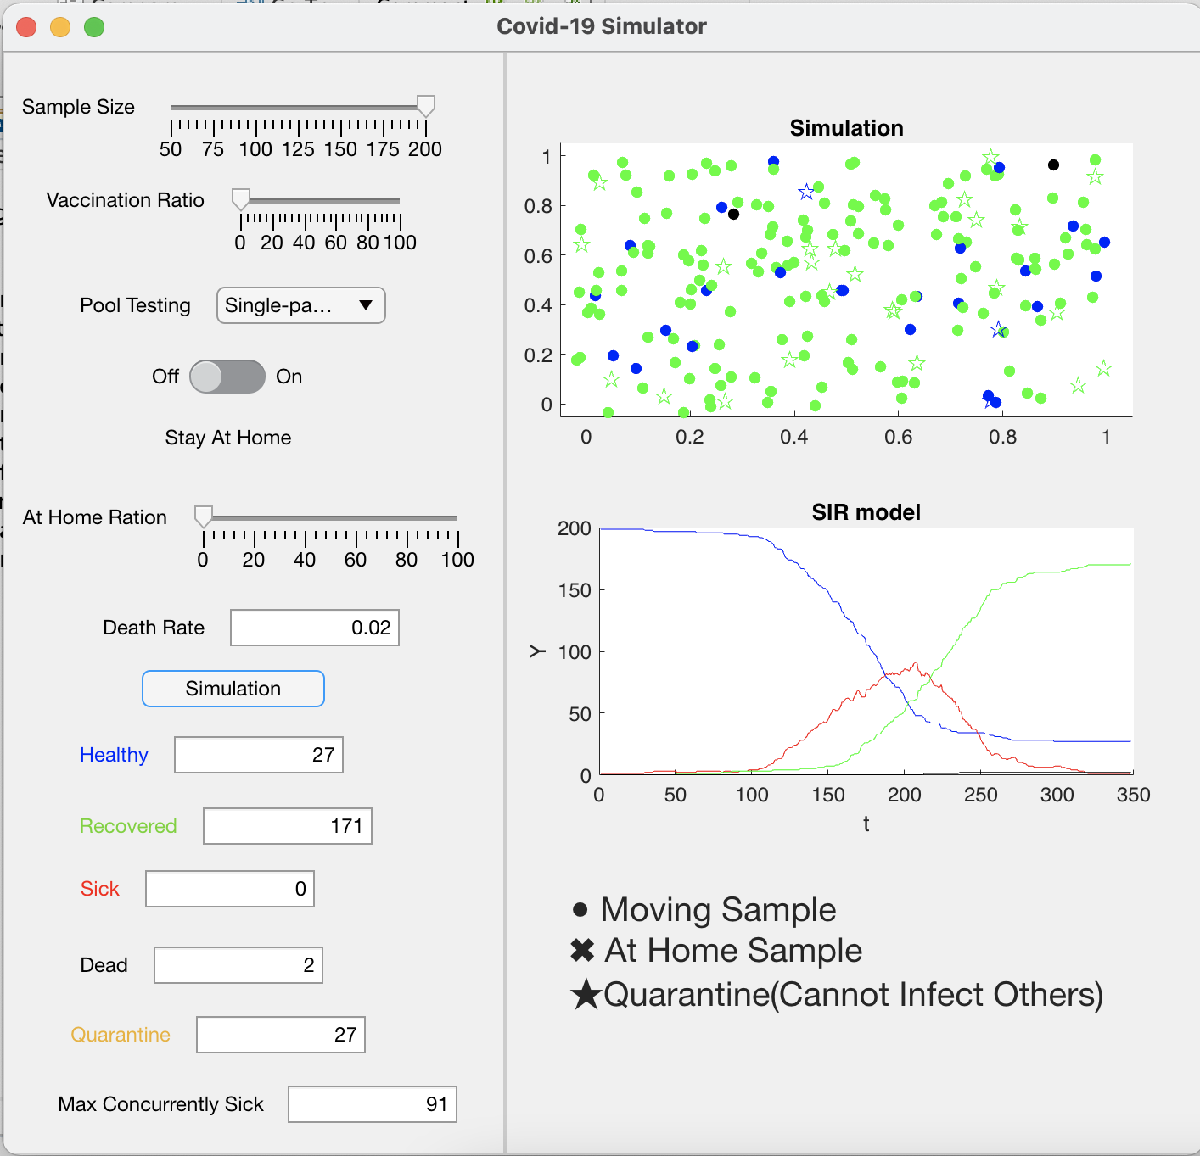

In city that have some sample size such as small city. Low social interaction with a small population will also reduce the cocurrently sick.

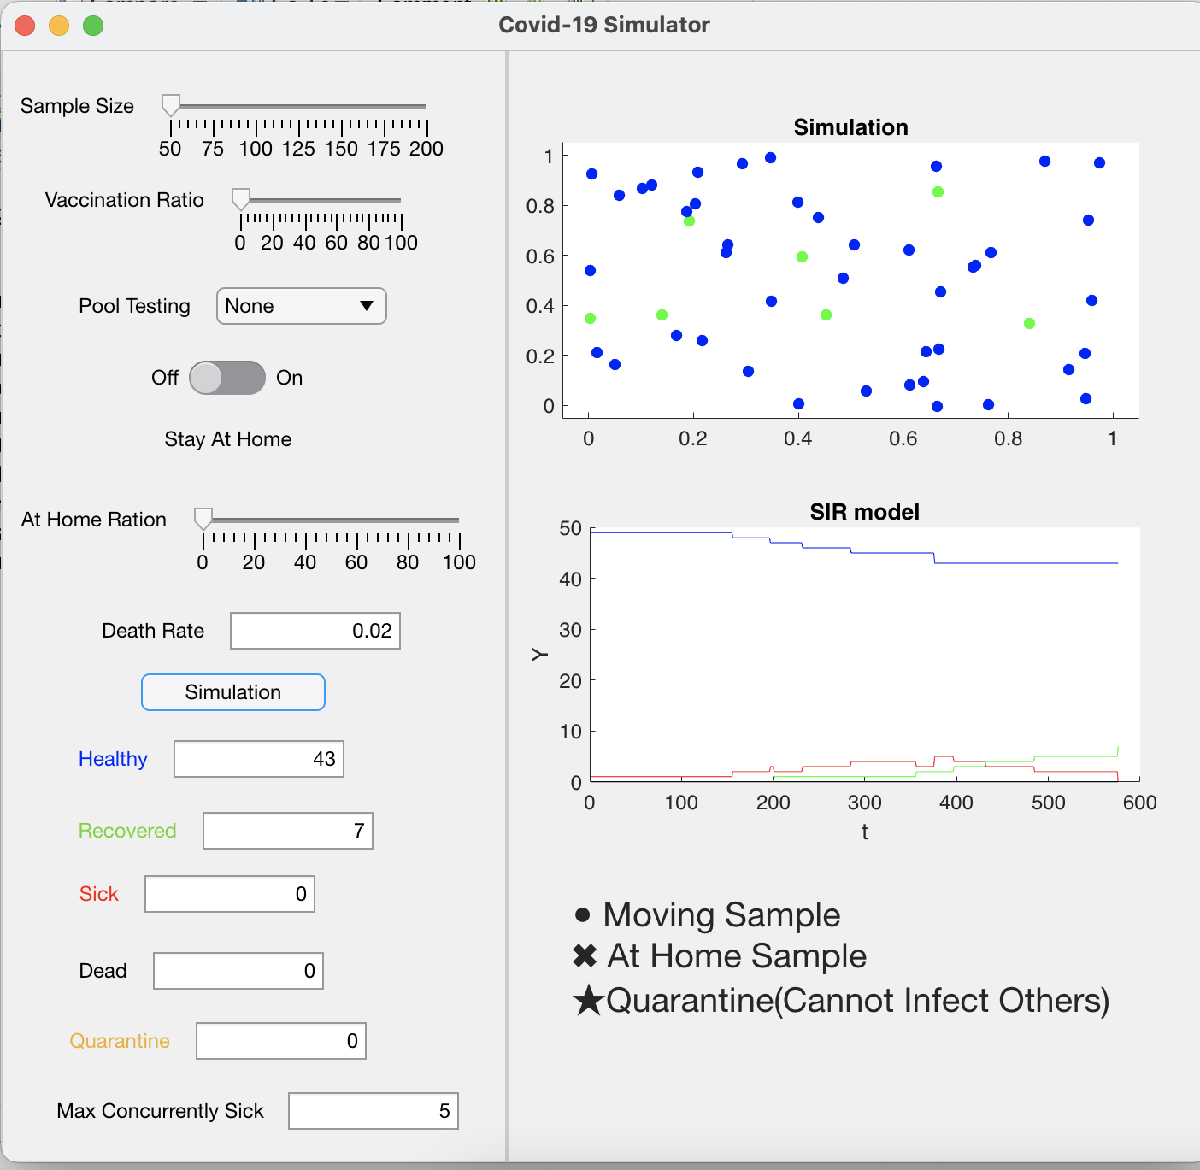

With vaccination ratio of 60%, it will reduce the spread of Covid-19 drastically.

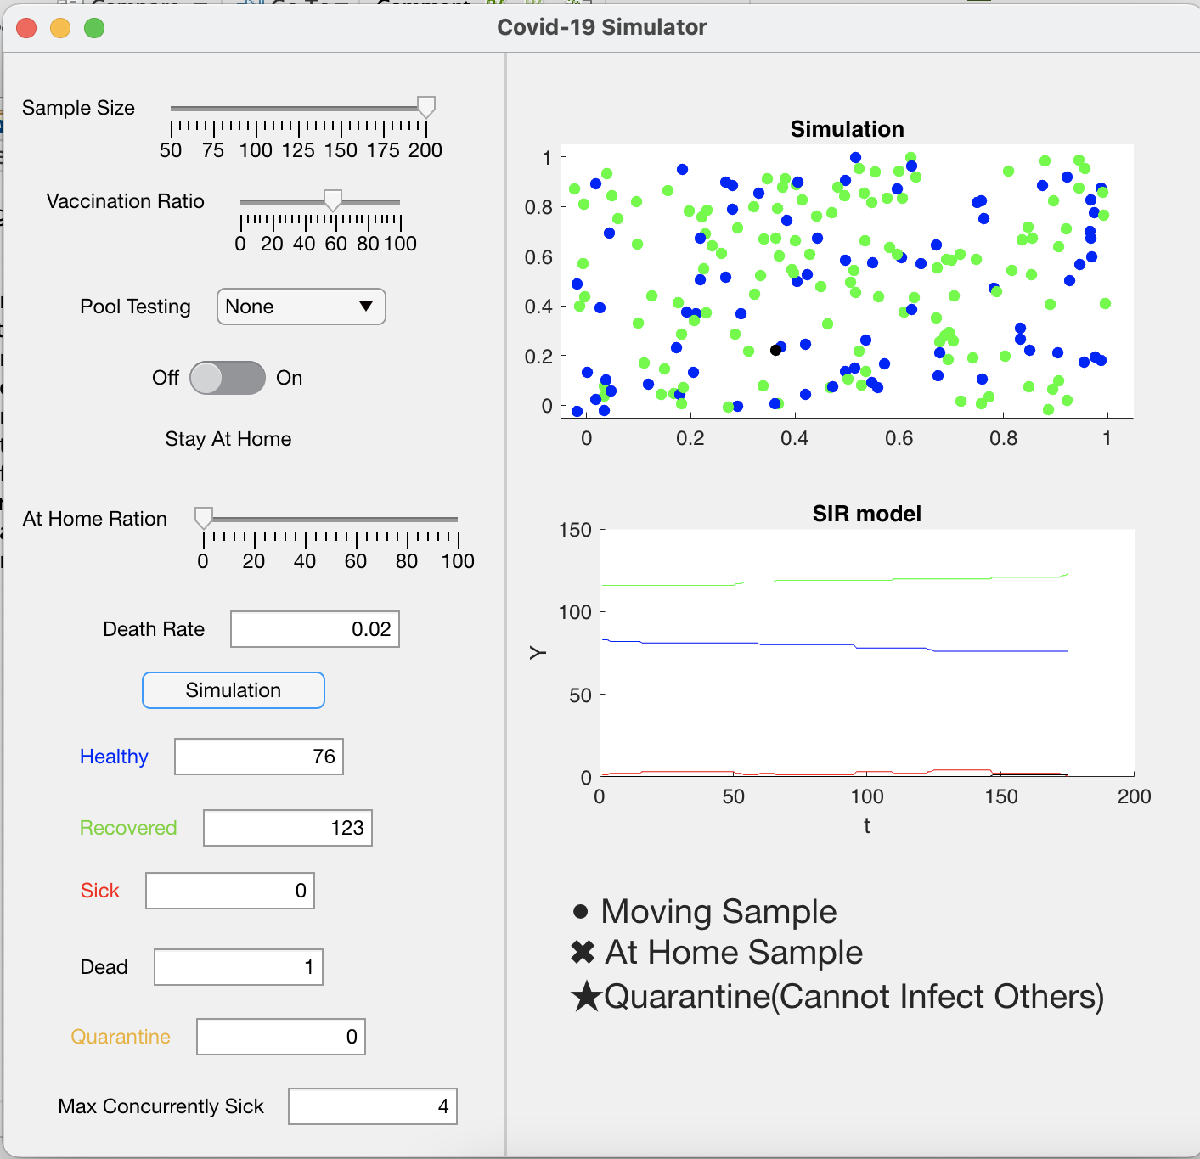

# Conclusion

In all case above, when social contact is reduced and more people get vaccinated, the max concurrently sick will reduce. However, two pass pool testing is very effective in detecting the sick population already.

# Reference

Nalbantoglu, Ozkan Ufuk. (2020). Group testing performance evaluation for SARS-CoV-2 massive scale screening and testing. *BMC Medical Research Methodology,* *20*(1), 176.

Based on:

[https://github.com/midudev/covid-19-spread-simulator](https://github.com/midudev/covid-19-spread-simulator)

[https://www.washingtonpost.com/graphics/2020/world/corona-simulator/](https://www.washingtonpost.com/graphics/2020/world/corona-simulator/)